# [Wind Power](https://apmonitor.com/pds/index.php/Main/WindPower)

Renewable energy such as wind power depends on weather systems that may not be synchronized with demand profiles. Wind and solar power is not dispatchable, meaning that generation depends on external environmental conditions that may be highly variable. It is important to know the expected power production from renewable energy so that backup power generation or energy storage can provide any shortfall between generation and demand.

Dispatchable power sources can be turned on by the grid operators. These include fast dispatchable power such as hydroelectric plants that can reach full output in less than a minute. Base-load nuclear plants require require hours or days to cycle off and then back on. Natural gas plants can reach full capacity within minutes. As the fraction of renewable power generation increases, it is important to know the anticipated power generation so that dispatchable sources can be scheduled to start when there is an increase in power demand or sudden decrease in renewable generation.

**Objective:** Develop a prediction of the wind power (kW) from prior wind speed (m/s), prior wind direction (degrees), and prior wind power (kW). Rank the most important factors from most important to least important. Randomly select values that split the data into a train (80%) and test (20%) set. Take two approaches. In the first approach, use [**Gradient Boosting (XGBoost)**](https://apmonitor.com/pds/index.php/Main/XGBoostRegressor) and a [**Neural Network (Deep Learning)**](https://apmonitor.com/pds/index.php/Main/MultilayerPerceptronNeuralNetwork). Use a single row of measurements to predict the wind power 10 minutes ahead. In the second approach, use a Recurrent Neural Network (LSTM). Use a window of 60 minutes of prior data to predict the wind power 10 minutes ahead. Discuss the performance of each with the Mean Absolute Error (MAE) for predicting wind power in the training and test set. Submit source code and a summary memo (max 2 pages) of your results.

**Regression:** Use 3 regression methods. [**Regression methods**](https://apmonitor.com/pds/notebooks/06_regression.html) are:

- [**XGBoost**](https://apmonitor.com/pds/index.php/Main/XGBoostRegressor)

- [**Neural Network (Deep Learning)**](https://apmonitor.com/pds/index.php/Main/MultilayerPerceptronNeuralNetwork)

- [**Recurrent Neural Network (LSTM)**](https://apmonitor.com/pds/index.php/Main/LongShortTermMemory)

**Data:** Data for a 3.6 MW wind turbine in Turkey is available for 1 year in 10 minute intervals.

[**Wind Power Data (10 min Intervals)**](https://apmonitor.com/pds/uploads/Main/wind.txt)

**Data          Description**

Time          Timestamp of the measurements taken every 10 minutes for 1 year

Direction    Angle of the wind turbine in degrees

Speed       Wind speed in meters/sec

Power       Electrical power produced by the wind turbine (3600 kW max)

The data set has bad data so data visualization and exploration are needed to first cleanse the data set. There are time periods where the wind turbine produces no power because of scheduled maintenance or inspection.

The [**TCLab Data Science modules 2-6**](https://github.com/APMonitor/data_science) ([**Import**](https://apmonitor.com/pds/notebooks/02_import_export.html), [**Analyze**](https://apmonitor.com/pds/notebooks/03_analyze.html), [**Visualize**](https://apmonitor.com/pds/notebooks/04_visualize.html), [**Prepare Data**](https://apmonitor.com/pds/notebooks/05_prepare_data.html), [**Regression**](https://apmonitor.com/pds/notebooks/06_regression.html)) are available as a template for analyzing and performing the regression. There are [**visualization and analysis notebooks on Kaggle**](https://www.kaggle.com/berkerisen/wind-turbine-scada-dataset/code) such as [**Wind Power Curve Modeling**](https://www.kaggle.com/winternguyen/wind-power-curve-modeling) that give additional insight on wind power predictions.

**References**

- Erisen, B. [**Wind Turbine Scada Dataset**](https://www.kaggle.com/berkerisen/wind-turbine-scada-dataset), Kaggle, Retrieved March 16, 2021.

## **Import Code**

url = 'http://apmonitor.com/pds/uploads/Main/wind.txt';
data = readtable(url);
head(data);

          Time          Direction    Speed     Power 
    ________________    _________    ______    ______

    2018-01-01 00:00     259.99      5.3113    380.05
    2018-01-01 00:10     268.64      5.6722    453.77
    2018-01-01 00:20     272.56       5.216    306.38
    2018-01-01 00:30     271.26      5.6597    419.65
    2018-01-01 00:40     265.67      5.5779    380.65
    2018-01-01 00:50     264.58      5.6041    402.39
    2018-01-01 01:00     266.16       5.793    447.61
    2018-01-01 01:10     257.95       5.306    387.24



## **Create Column for Future**

Future = data.Power;
Future(1:end-1) = data.Power(2:end);
data.Future = Future;

## Statistics

statistics(data.Direction)

ans = struct with fields:
    count: 50530
     mean: 123.6876
      std: 93.4437
      min: 0
      max: 359.9976
       Q1: 49.3152
       Q2: 73.7130
       Q3: 201.6968


statistics(data.Speed)

ans = struct with fields:
    count: 50530
     mean: 7.5580
      std: 4.2272
      min: 0
      max: 25.2060
       Q1: 4.2014
       Q2: 7.1046
       Q3: 10.3001


statistics(data.Power)

ans = struct with fields:
    count: 50530
     mean: 1.3077e+03
      std: 1.3125e+03
      min: -2.4714
      max: 3.6187e+03
       Q1: 50.6651
       Q2: 825.8381
       Q3: 2.4825e+03


statistics(data.Future)

ans = struct with fields:
    count: 50530
     mean: 1.3077e+03
      std: 1.3125e+03
      min: -2.4714
      max: 3.6187e+03
       Q1: 50.6651
       Q2: 825.9444
       Q3: 2.4825e+03


## Data Cleansing

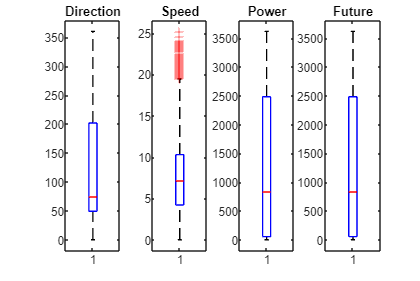

% View the data with boxplots
features = {'Direction', 'Speed', 'Power', 'Future'};
figure('Position', [0, 0, 1200, 800]);
hold on;
for i = 1:numel(features)
    subplot(1, 4, i);
    boxplot(data.(features{i}));
    title(features{i});
end
hold off;

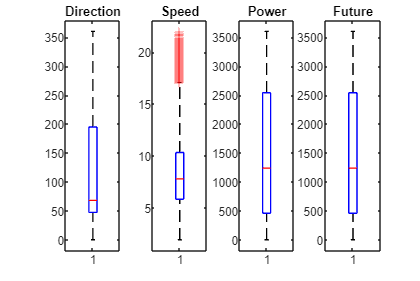


% Clean the data
data = data(data.Speed < 22 ,:);
data = data(data.Power > 0 , :);
data = data(data.Future > 0, :);
data = data(data.Power < 3600,:);
data = data(data.Future < 3600, :);

% Check the data again with boxplots
features = {'Direction', 'Speed', 'Power', 'Future'};
figure('Position', [0, 0, 1200, 800]);
hold on;
for i = 1:numel(features)
    subplot(1, 4, i);
    boxplot(data.(features{i}));
    title(features{i});
end
hold off;


% View the statistics
statistics(data.Direction)

ans = struct with fields:
    count: 35671
     mean: 111.0156
      std: 86.3240
      min: 0
      max: 359.9976
       Q1: 47.2122
       Q2: 67.9666
       Q3: 194.8444


statistics(data.Speed)

ans = struct with fields:
    count: 35671
     mean: 8.1946
      std: 3.0944
      min: 1.9290
      max: 21.9954
       Q1: 5.8287
       Q2: 7.7914
       Q3: 10.3237


statistics(data.Power)

ans = struct with fields:
    count: 35671
     mean: 1.5154e+03
      std: 1.1659e+03
      min: 0.0345
      max: 3.6000e+03
       Q1: 458.2274
       Q2: 1.2368e+03
       Q3: 2.5385e+03


statistics(data.Future)

ans = struct with fields:
    count: 35671
     mean: 1.5147e+03
      std: 1.1667e+03
      min: 2.0000e-04
      max: 3.6000e+03
       Q1: 457.9970
       Q2: 1.2371e+03
       Q3: 2.5387e+03


This next line of code requires [**Econometrics Toolbox**](https://www.mathworks.com/products/econometrics.html)**.**

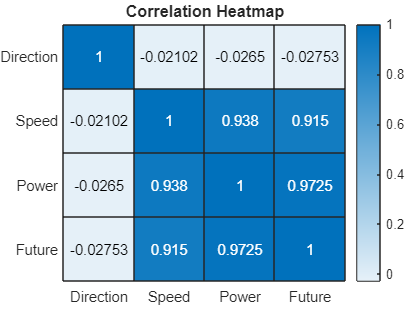

% Compute correlation matrix
corrMatrix = corr(data{:,2:end});

% Create correlation heatmap
figure
heatmap(data.Properties.VariableNames(:,2:end), data.Properties.VariableNames(:,2:end), corrMatrix);
title('Correlation Heatmap');

## Data Scaling

% Grab the features and not the time column
data = data(:,features);

% Scale the data
Z = zscore(table2array(data));
data_s = array2table(Z, 'VariableNames', data.Properties.VariableNames);

% Split data into X and y
Xfeatures = {'Direction', 'Speed', 'Power'};
X = data_s(:, Xfeatures);
y = data_s.Future;

% Find number of samples
n_samples = height(data_s(:,1));

% Train/test split
[trainID,~,testID] = dividerand(n_samples,0.8,0,0.2);
XTrain = X(trainID,:);
XTest = X(testID,:);
YTrain = y(trainID);
YTest = y(testID);

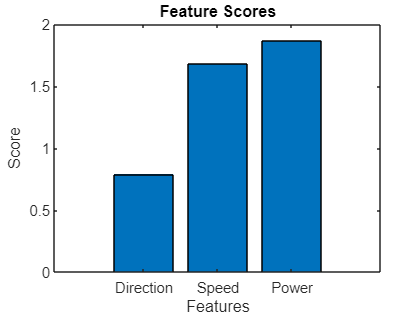

% Fit SelectKBest on training data
[fit,scores] = fscchi2(XTrain, YTrain);

% Plot feature scores as a bar plot
figure;
bar(scores);
xticklabels({"Direction","Speed","Power"});
xlabel('Features');
ylabel('Score');
title('Feature Scores');

The most important features to predict the wind power in 10 minutes in order are the 10 minute prior wind power, speed, and direction.

## Regression

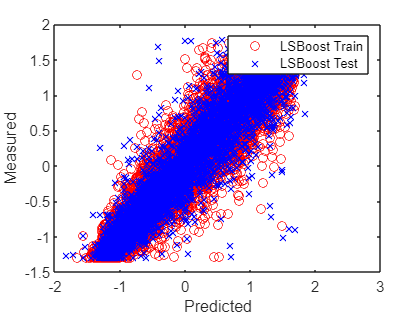

% train LSBoost model
xgb = fitrensemble(XTrain, YTrain, 'Method', 'LSBoost');

% Create MLPRegressor
nn = fitrnet(XTrain, YTrain);

% Calculate the predicted values for each fit and data set
xgbTrain = predict(xgb,XTrain);
xgbTest = predict(xgb,XTest);
nnTrain = predict(nn,XTrain);
nnTest = predict(nn,XTest);

% Plot predicted values from fit
% xgb regressor
figure;
plot(xgbTrain,YTrain,'ro','DisplayName','LSBoost Train');
hold on;
plot(xgbTest,YTest,'bx','DisplayName','LSBoost Test');
xlabel('Predicted');
ylabel('Measured');
legend;
hold off;

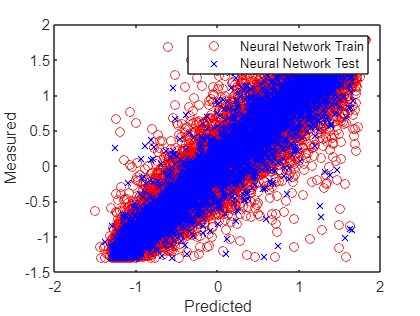


% neural network
figure;
plot(nnTrain,YTrain,'ro','DisplayName','Neural Network Train');
hold on;
plot(nnTest,YTest,'bx','DisplayName','Neural Network Test');
xlabel('Predicted');
ylabel('Measured');
legend;
hold off;

### Regressor Analysis

% Estimate the loss
xgbTrain_mae = crossval('mse',xgbTrain,YTrain,'Predfun',@regf)

xgbTrain_mae = 0.0411

xgbTest_mae = crossval('mse',xgbTest,YTest,'Predfun',@regf)

xgbTest_mae = 0.0642

nnTrain_mae = crossval('mse',nnTrain,YTrain,'Predfun',@regf)

nnTrain_mae = 0.0525

nnTest_mae = crossval('mse',nnTest,YTest,'Predfun',@regf)

nnTest_mae = 0.0548


% R2 score
xgbTrain_r2 = r2_score(xgbTrain,YTrain)

xgbTrain_r2 = 0.9571

xgbTest_r2 = r2_score(xgbTest,YTest)

xgbTest_r2 = 0.9326

nnTrain_r2 = r2_score(nnTrain,YTrain)

nnTrain_r2 = 0.9446

nnTest_r2 = r2_score(nnTest,YTest)

nnTest_r2 = 0.9419

## Train LSTM

The code below took 8 minutes to run on a computer with the following specs.

Processor	11th Gen Intel(R) Core(TM) i7-1195G7 @ 2.90GHz   2.92 GHz

Installed RAM	16.0 GB (15.8 GB usable)

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:14 |         1.02 |          0.5 |          0.0010 |
|      25 |          25 |       00:07:49 |         0.42 |      8.8e-02 |          0.0010 |
|========================================================================================|
Training finished: Max epochs completed.


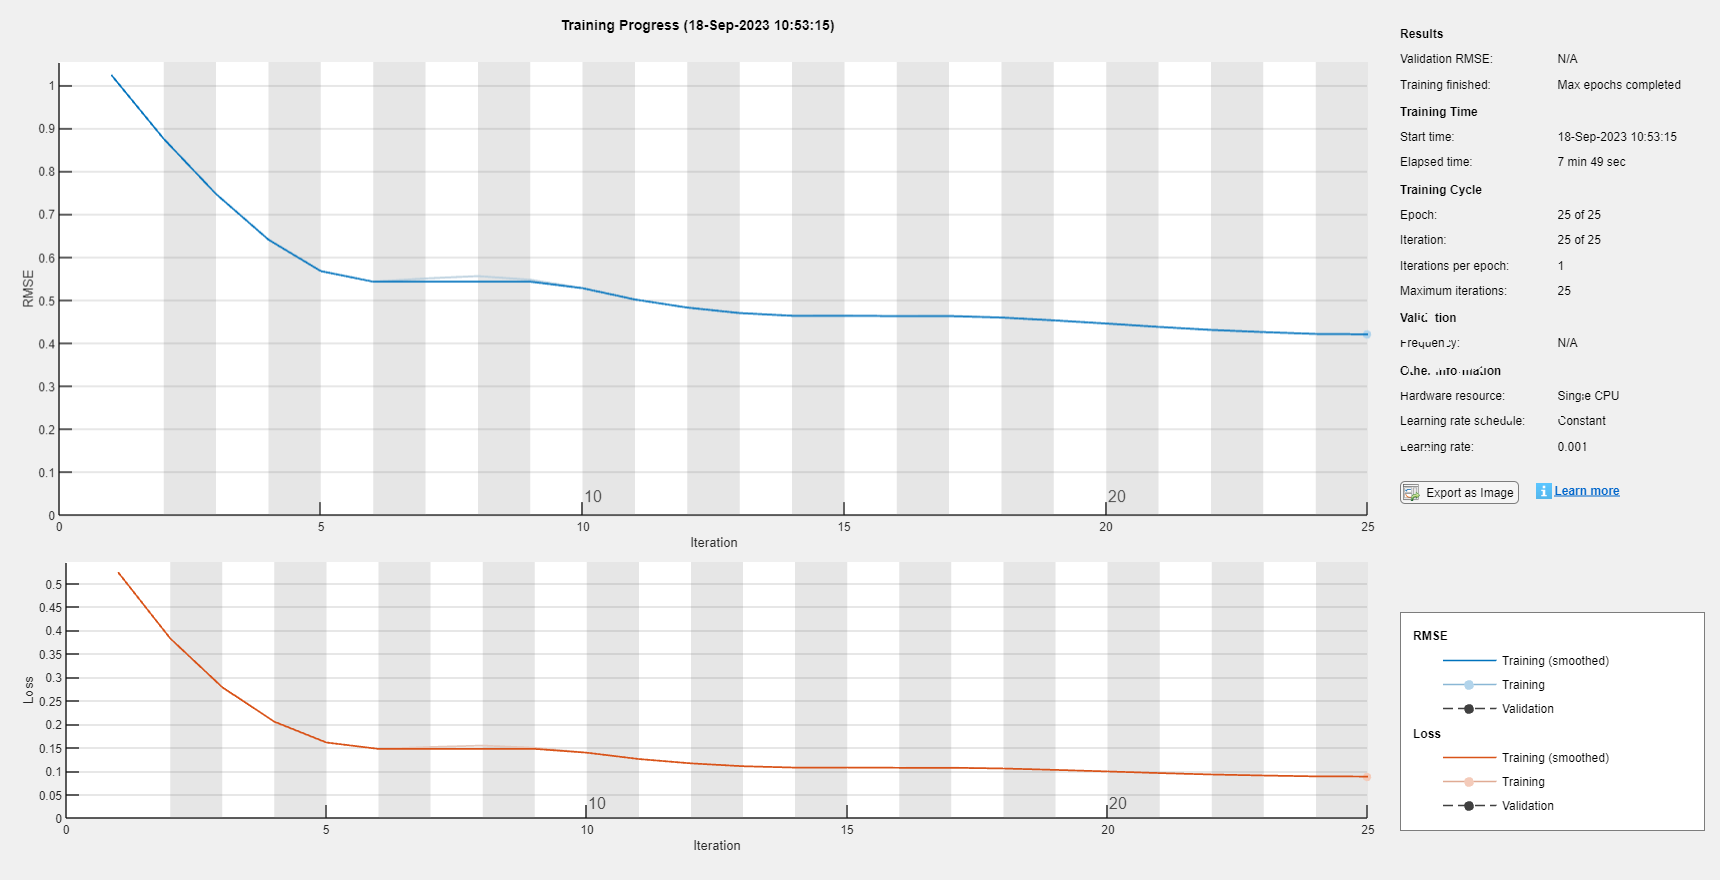

% Set up layers for the LSTM
layers = [ sequenceInputLayer(3)
    lstmLayer(75)
    dropoutLayer(0.2)
    lstmLayer(75)
    dropoutLayer(0.2)
    fullyConnectedLayer(1)
    regressionLayer
    ];

% Clarify more options for the fit
options = trainingOptions('adam', ...
    MaxEpochs=25, ...
    MiniBatchSize=100, ...
    Verbose=true, ...
    Plots='training-progress');

[lstm,info] = trainNetwork(table2array(XTrain)',YTrain',layers,options);

fprintf('LSTM Train MAE is %.6f\n', info.TrainingLoss(end));

LSTM Train MAE is 0.088412


fprintf('LSTM Test MAE is %.6f\n', info.TrainingRMSE(end));

LSTM Test MAE is 0.420505


## Supporting Functions

function statistics = statistics(data)
    statistics.count = numel(data); % count
    statistics.mean = mean(data); % mean
    statistics.std = std(data); % standard deviation
    statistics.min = min(data); % min
    statistics.max = max(data); % max
    statistics.Q1 = prctile(data,25); % 1st quartile (25th percentile)
    statistics.Q2 = prctile(data,50); % 2nd quartile (50th percentile) = median
    statistics.Q3 = prctile(data,75); % 3rd quartile (75th percentile)
end

function yfit = regf(Xtrain,ytrain,Xtest)
b = regress(ytrain,Xtrain);
yfit = Xtest*b;
end